this file shows some examples of L-scale and how it compairs to similar features such as standard diviation and absolute diviation. 

L-scale should be less impacted by outliers then standard diviation and absolute diviation


a = rand(1, 10) %vector of 10 dimentions with values between 0 and 1

a =     0.3420    0.2555    0.2327    0.7611    0.9435    0.4778    0.0308    0.5921    0.3368    0.5041


lscale(a)

ans =     0.4477    0.1581


std(a)

ans = 0.2686

sum(abs(a-mean(a)))./length(a)

ans = 0.2081



b = [.84, .52, 30, .75, .04, .32, .24, .91, .06, .86] %vector with a single outlier of 30 

b =     0.8400    0.5200  300.0000    0.7500    0.0400    0.3200    0.2400    0.9100    0.0600    0.8600


lscale(b)

ans =    30.4540   30.1164


std(b)

ans = 94.7094

sum(abs(b-mean(b)))./length(b)

ans = 53.9092



c = a*1000 %vector with higher magnatude 

c =   342.0296  255.5315  232.6785  761.1169  943.4504  477.8203   30.8437  592.1195  336.7732  504.1411


lscale(c)

ans =   447.6505  158.1485


std(c)

ans = 268.6079

sum(abs(c-mean(c)))./length(c)

ans = 208.0792



d = [.84, .52, -20, .75, .04, .32, .24, .91, 45, .86] %two outliers: -20 and 45

d =     0.8400    0.5200  -20.0000    0.7500    0.0400    0.3200    0.2400    0.9100   45.0000    0.8600


lscale(d)

ans =     2.9480    6.6220


std(d)

ans = 16.1292

sum(abs(d-mean(d)))./length(d)

ans = 8.4104

Now here are some examples using EMG data 

sig1 = EEG.data(1,:,1);
lscale(sig1)

ans = 1×2 single row vector
    7.3730   92.3332


std(sig1)

ans = single
188.7788

sum(abs(sig1-mean(sig1)))./length(sig1)

ans = single
121.9783

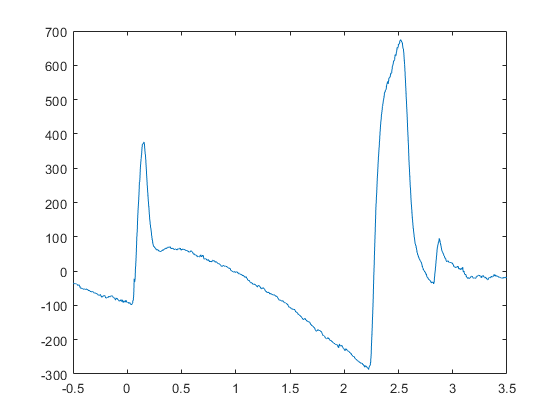

plot(EEG.timessec,squeeze(EEG.data(1,:,1)))



sig2 = EEG.data(1,:,2);
lscale(sig2)

ans = 1×2 single row vector
   15.2681  101.2344


std(sig2)

ans = single
195.8542

sum(abs(sig2-mean(sig2)))./length(sig2)

ans = single
133.1775

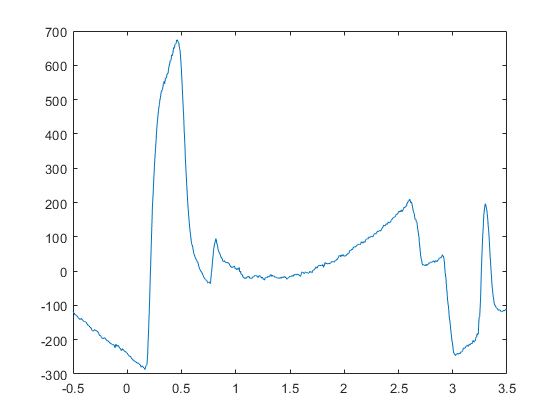

plot(EEG.timessec,squeeze(EEG.data(1,:,2)))



sig3 = EEG.data(1,:,7);
lscale(sig3)

ans = 1×2 single row vector
    5.8813   48.7285


lm(sig3, 2)

ans = 1×2 single row vector
    5.8813  128.8052


std(sig3)

ans = single
121.0967

sum(abs(sig3-mean(sig3)))./length(sig3)

ans = single
67.6217

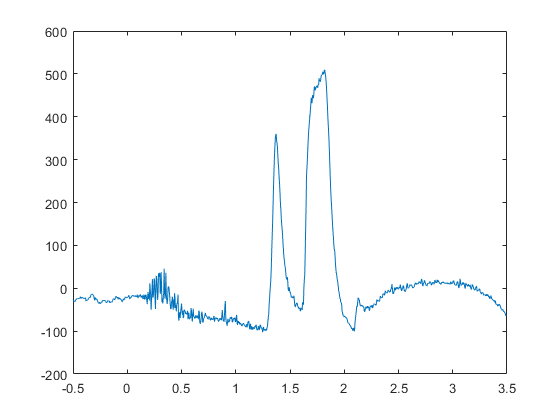

plot(EEG.timessec,squeeze(EEG.data(1,:,7)))



sig4 = EEG.data(1,:,9);
lscale(sig4)

ans = 1×2 single row vector
   -3.5493  136.0054


lm(sig4, 2)

ans = 1×2 single row vector
   -3.5493 -347.8210


std(sig4)

ans = single
268.6506

sum(abs(sig4-mean(sig4)))./length(sig4)

ans = single
171.4475

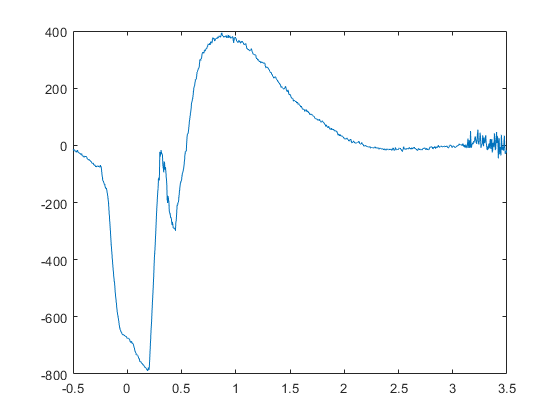

plot(EEG.timessec,squeeze(EEG.data(1,:,9)))


%test


